%% LQR and LQI Controller

clc;
close all;
clear all;


%% Part 1: LQR (Continuous)

% 1.1) Continuous Time Plant

A = [0    1    0;
     0    0    1;
    -505 -111  -7];

B = [0;
     0;
     1];

C = [1 0 0];
D = 0;

% Eigenvalues
eig(A)

ans =   -5.0000 + 0.0000i
  -1.0000 +10.0000i
  -1.0000 -10.0000i



% Controllability
rank(ctrb(A,B))

ans = 3


% Observability
rank(obsv(A,C))

ans = 3


% System
Gp_ss = ss(A,B,C,D);

figure,step(Gp_ss);
grid on


%% 1.2) Solve for LQR Gain (Method 1, Manual Cal)

% X_dot = AX + BU
%
% J = âˆ«0âˆžâ€‹ (x'Qx + u'Ru) dt
% 
% A'P + PA âˆ’ PBR^-1B'P + Q = 0
% 
% K = R^âˆ’1 B' P

% R: Penalizes control effort. 
% Small R = Aggressive control, Large R = Cheap/Lazy control.
R = 0.1; 

% 4. Compute Optimal Gain K using the Riccati Equation
% MATLAB solves: A'P + PA - PBR^-1B'P + Q = 0
Q = 10^0 * [10^0  0     0;
             0     10^0  0;
             0     0     10^0];


R = 10^-3;

% Solve Riccati Equation (P+)

[P, ~, ~] = care(A,B,Q,R)

P =    47.4313   14.2543    0.0010
   14.2543    6.4125    0.0935
    0.0010    0.0935    0.0282


disp('Riccati Solution P+ = ')

Riccati Solution P+ = 


disp(P)

   47.4313   14.2543    0.0010
   14.2543    6.4125    0.0935
    0.0010    0.0935    0.0282




% Compute Gain manually
K = inv(R)*B'*P

K =     0.9891   93.5228   28.1574



disp('Gain K = ')

Gain K = 


disp(K)

    0.9891   93.5228   28.1574




% Closed loop
Acl = A - B*K

Acl =          0    1.0000         0
         0         0    1.0000
 -505.9891 -204.5228  -35.1574




disp('Closed loop eigenvalues = ')

Closed loop eigenvalues = 


eig(Acl)

ans =  -28.6314 + 0.0000i
  -3.2630 + 2.6505i
  -3.2630 - 2.6505i



% System simulation
Gp_ss_cl1 = ss(Acl,B,C,D)


Gp_ss_cl1 =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0       0       1
   x3    -506  -204.5  -35.16
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.





close all;
figure, step(Gp_ss_cl1)
grid on
title('LQR using CARE (manual K)')


% Add feedforward Gain correction with dc gain close loop
FF = 1/dcgain(Gp_ss_cl1)

FF = 505.9891



Bcl = B*FF

Bcl =          0
         0
  505.9891


Acl = A-B*K

Acl =          0    1.0000         0
         0         0    1.0000
 -505.9891 -204.5228  -35.1574


Ccl = C

Ccl =      1     0     0


Dcl = D

Dcl = 0


Gp_ss_cl1_FF = ss(Acl,Bcl,Ccl,Dcl)


Gp_ss_cl1_FF =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0       0       1
   x3    -506  -204.5  -35.16
 
  B = 
        u1
   x1    0
   x2    0
   x3  506
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



figure,step(Gp_ss, Gp_ss_cl1, Gp_ss_cl1_FF);
grid on
title('LQR with Feedforward (Step -> 1)');


%% 1.3) Use default LQR command

% ...;  K-->Gain, S-->P (Sol Ricatti), P-->CLPoles

% [K2, P2, Poles_CL2] = []...

% System simulation
K = lqr(Gp_ss,Q,R,[])

K =     0.9891   93.5228   28.1574


A = Gp_ss.A;
B = Gp_ss.B;
C = Gp_ss.C;
D = Gp_ss.D;

Acl = A - B*K;

Gp_ss_cl2 = ss(Acl, B, C, D);
close all;
figure, step(Gp_ss_cl2)
grid on
title('LQR using CARE (manual K)')


% Add feedforward Gain correction
% FF2 = []

K = lqr(Gp_ss, Q, R);

A = Gp_ss.A;
B = Gp_ss.B;
C = Gp_ss.C;
D = Gp_ss.D;

Acl = A - B*K;

N = -1 / (C * inv(Acl) * B);
Acl2 = A - B*K;
Bcl2 = B*N;
Ccl2 = C;
Dcl2 = D;

Gp_ss_cl2_FF = ss(Acl2, Bcl2, Ccl2, Dcl2);

figure,step(Gp_ss, Gp_ss_cl2, Gp_ss_cl2_FF);
grid on
title('LQR with Feedforward (Step -> 1)');



figure,step(Gp_ss_cl1_FF, 'b'); hold on;
step(Gp_ss_cl2_FF, 'r--'); grid on;



%% Part 2: Discrete LQR

Ts = 10^-3; % 1ms Sampling time

% 1. Discretize the continuous system using Zero-Order Hold (ZOH)
% Assuming Gp_ss was defined in your previous continuous-time section
Gpz_ss = c2d(Gp_ss, Ts, 'zoh');

Ad = Gpz_ss.A;
Bd = Gpz_ss.B;
Cd = Gpz_ss.C;
Dd = Gpz_ss.D;

% 2. Define Discrete Weighting Matrices
Qz = eye(3) * 1; % Based on your Qz = 10^0 * [1 0 0; 0 1 0; 0 0 1]
Rz = 10^-3;

% 3. Solve Discrete LQR (DLQR)
% [K, S, e] = dlqr(A, B, Q, R)
[K3, P3, Poles_CL3] = dlqr(Ad, Bd, Qz, Rz);

% 4. Construct Closed Loop System
% Note: In discrete time, stability requires eigenvalues to be INSIDE the unit circle (|z| < 1)
Aclz = Ad - Bd * K3;
Gpz_ss_cl1 = ss(Aclz, Bd, Cd, Dd, Ts);

disp('Closed loop discrete eigenvalues = ')

Closed loop discrete eigenvalues = 


disp(eig(Aclz))

   0.9718 + 0.0000i
   0.9967 + 0.0026i
   0.9967 - 0.0026i



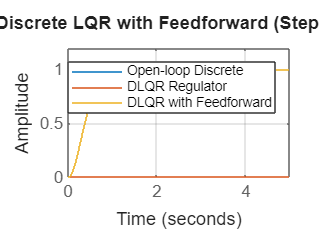


% 5. Add Feedforward Gain Correction
% The formula for DC gain in discrete time is the same: 1 / (C * (I - (A-BK))^-1 * B)
FFz2 = 1 / dcgain(Gpz_ss_cl1);

% Scaled matrices for tracking
Bclz2 = Bd * FFz2;
Aclz2 = Aclz;
Cclz2 = Cd;
Dclz2 = Dd;

Gpz_ss_cl1_FF = ss(Aclz2, Bclz2, Cclz2, Dclz2, Ts);

% 6. Visualization
close all;
figure;
step(Gpz_ss, Gpz_ss_cl1, Gpz_ss_cl1_FF);
grid on
legend('Open-loop Discrete', 'DLQR Regulator', 'DLQR with Feedforward');
title('Discrete LQR with Feedforward (Step -> 1)');

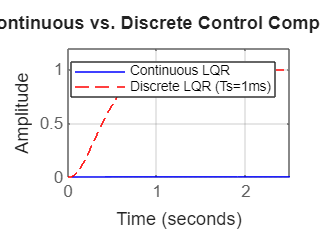


% Comparison of Continuous vs Discrete response
figure;
step(Gp_ss_cl1, 'b'); hold on; % From your continuous Part 1
step(Gpz_ss_cl1_FF, 'r--'); 
grid on;
legend('Continuous LQR', 'Discrete LQR (Ts=1ms)');
title('Continuous vs. Discrete Control Comparison');




%% Part 3: LQI 

% Further Reading LQI command 
% https://www.mathworks.com/help/control/ref/ss.lqi.html


